# Example: Solving the emission circuit for a tree-like graph state

### State preparation:

Create the adjacency matrix `Gamma` of a simple connected graph:

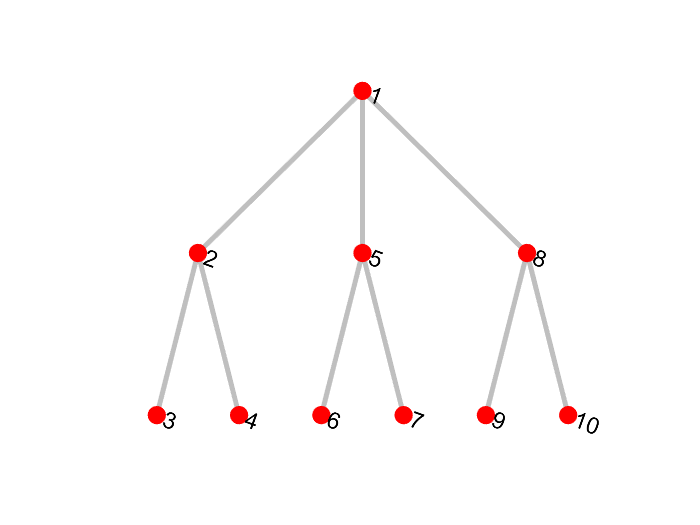

clear
filename = 'State1'; % filename
n = 10; % qubits number of target photonic state 
EdgeList = [1,2;1,5;1,8; 2,3;2,4; 5,6;5,7; 8,9;8,10]; % the list for edges
Gamma = full(sparse(EdgeList,fliplr(EdgeList),ones(size(EdgeList)),n,n));
figure;
plot(graph(Gamma),'MarkerSize',10,'NodeColor','r','EdgeColor',0.5*[1,1,1], ...
    'LineWidth',3,'NodeFontSize',14);
axis off

Where `Gamma` cannot have zero row and column, which represents 'decoupled qubit'. Quantum state with decoupled qubits is trivial and they could obstruct the algorithm, if they were placed at improper positions of the sequence.

Create the stabilizer generators `Gen` in the following way:

Gen.Tableau = [eye(n),Gamma]; % Tableau matrix for generators.
Gen.SignVector = zeros(n,1); 
% The vector that represents the signs 
%  in front of these generators: 0 for '+', 1 for '-'.

Where` tableau` is a way of representing Pauli matrices $\{I,X,Y,Z\}$ in $\mathbb{F}_2^2$ as $(0,0),\;
(1,0),\;
(1,1),\;
(0,1)$. In this representation, the multiplication is replaced by addition, with phases being ignored. The phases are stored in `SignVector` instead (The concrete rules are shown  in [PhysRevA.70.052328](https://journals.aps.org/pra/abstract/10.1103/PhysRevA.70.052328)). For example, the generators for bell state $|\Psi^+\rangle\equiv\frac{|01\rangle +|10\rangle}{\sqrt{2}}$ can be written as$g_1 = X_1X_2, g_2 = -Z_1Z_2$, which are represented as:

`Gen.Tableau = [1,1,0,0;`

`               0,0,1,1];`

`Gen.SignVector = [0;1];`

Similarily, we can replace `Gen` by any pure stabilizer state. Use following code to load logical $|-\rangle_L$ state of Shor code from the root directory:

% load('ShorCode_x1.mat','Gen');

For pure stabilizer state with $n$ qubits, `Gen.Tableau` has to be an $n\times 2n$ full rank matrix, and `Gen.SignVector` has to be an column vector of length $n$.

### Circuit solver:

Solve the circuit with `Gen` :

[Operation,InvOperation,Stat] = CircuitSolver(Gen);

	** The protocol is SOLVED correctly! **


where

- `Operation` records the data of $\{U_{e,j},U_{p,j},\eta_j,\mu_j,W_j,W_0\}$operations. Any unitary operator in `Operation` acts on the stabilizer by $g' = U^\dagger g U$. If $g_i|\psi_B\rangle =|\psi_B\rangle, \forall g_i\in \mathcal{G}_B$ , $g'_i|\psi_A\rangle =|\psi_A\rangle, \forall g'_i\in \mathcal{G}_A$, and $\mathcal{G}_B, \mathcal{G}_A$ are related by successive transformation $\mathcal{G}_A =U_2^\dagger U_1^\dagger  \mathcal{G}_B U_1 U_2 $, then $|\psi_B\rangle  = U_1U_2|\psi_A\rangle$.

- `InvOperation` is the similar operation set as `Operation` but with *reversed* unitaries. For instance: $P\to P^{-1}  = PZ$. `InvOperation` is for verification purpose, which recovers $\mathcal{G}_f$ from $\mathcal{G}_0$.

- `Stat` is the other data like height function, single qubit gates number, two-qubit gates number *et al*.

- Output "`SOLVED correctly`" means all of the generators has reduced to $+Z_i$.

The step-by-step mechanism of CircuitSolver is displayed in `FlowChartMaker.mlx `in the root directory.

In the function `CircuitSolver`, we can change "photon absorption" and "time-reversed measurement" preference by modifying line 

`eta = n_p + e_v_a(1); `

and line

`mu = n_p + e_v_b(1);`

They are originally set as the left most non-trivial emitter.

### Result Verification:

Verify if the output of `CircuitSolver` gives the correct state in normal time order, using stabilizer formalism.

[G_f_recover, G_Phi_recover] = ...
    ProtocolExecutor(InvOperation,Stat.EmittersNumber,Stat.PhotonsNumber); 
Equivalence = GeneratorsEquivalence(Gen,G_Phi_recover) 

Equivalence = struct with fields:
       Overall: 1
       Tableau: 1
    SignVector: 1


% check the equivalence of Tableaus and SignVectors

where

- `G_f_recover` is the final outcomes stabilizer generators of "photons + emitters" system.

- `G_Phi_recover` is the final outcomes stabilizer generators of photons only.

- `ProtocolExecutor` executes the emission circuit. When measurement in normal time order occurs, `ProtocolExecutor` simulates the measurement outcomes with 50% `0` and 50% chance `1`, followed by conditional flipping on the corresponding photon.

- `GeneratorsEquivalence` examines the gauge equivalence of two generator sets.

### Display the circuit:

Print the $\mathrm{TeX}$ codes in a `quantikz_filename.txt` file for [quantikz](https://www.ctan.org/pkg/quantikz), which displays an easy-to-read circuit with $\mathrm{TeX}$ compiler.

Operation2quantikz(Operation,Stat.PhotonsNumber,Stat.EmittersNumber,filename);

	** The quantikz code for latex has been saved as: quantikz_State1.txt ** 


When compiling $\mathrm{TeX}$, we need to load:

`\usepackage{tikz} `

`\usetikzlibrary{quantikz}`

in the $\mathrm{TeX}$ compiler.   To compile and display the circuit, please copy-paste the codes in `quantikz_filename.txt` between `\begin{document}` and `\end{document}`.

**Caveat:** when n > 100, the circuit display with `quantikz` is dense, and the $\mathrm{TeX}$ compilation could be slow. One may want to display the circuit with plain text (less readable) by the following compromising approach, which converts and saves the circuit solution in `ProtocolReport_filename.txt`:

ProtocolPrinter(Operation,Stat,filename);



 	 *** The protocol has been saved as ProtocolReport_State1.txt  ***.
 


Plot the height function $h_p(x)$ for the target photonic state.

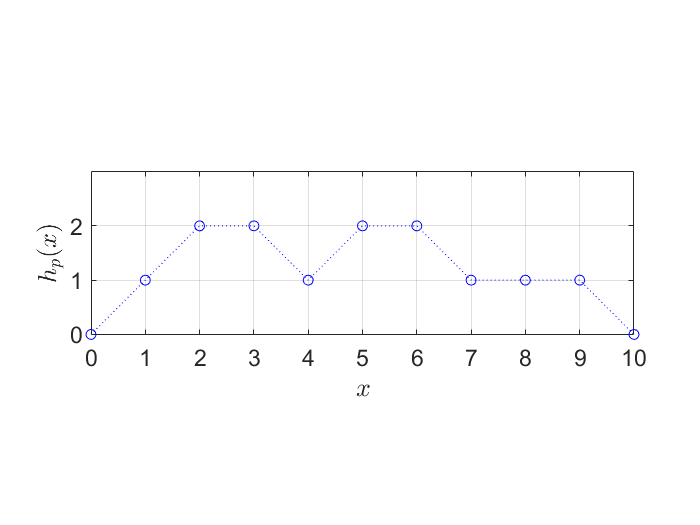

figure;
h = Stat.HeightFunc; % The height function of target photonic state.
plot(0:n,[0,h],':ob');
grid on
ax = gca;
xlabel('$x$','Interpreter','latex');
ylabel('$h_p(x)$','Interpreter','latex');
set(ax,'XTick',unique( round(ax.XTick)),'YTick',unique( round(ax.YTick) ), ...
    'XLim',[0,n],'YLim',[0,max(h)+1],'FontSize',14)
daspect([1,1,1]);

Where `h` is also accessible directly through:

% h = heightfunc(Gen.Tableau,'pure');